f = @(x) 0.01*sin(10*x(1))+(0.07*x(1).^2-0.4).^2

f = function_handle with value:
    @(x)0.01*sin(10*x(1))+(0.07*x(1).^2-0.4).^2



px = [-10 -5 0 5 10];
py = [0.0001 -0.1 0 0.1 -0.0001];
stopien=5

stopien = 5

W = polyfit(px, py, stopien)

W =    -0.0000    0.0000    0.0011   -0.0000         0    0.0000


fx=@(x)(0.05*sin(1*x)+W(1)*x.^stopien+W(2)*x.^(stopien-1)+W(3)*x.^(stopien-2)+W(4)*x.^(stopien-3)+W(5)*x.^(stopien-4)+W(6)*x.^(stopien-5))*(0.001*sin(x/10))+0.000001*x

fx = function_handle with value:
    @(x)(0.05*sin(1*x)+W(1)*x.^stopien+W(2)*x.^(stopien-1)+W(3)*x.^(stopien-2)+W(4)*x.^(stopien-3)+W(5)*x.^(stopien-4)+W(6)*x.^(stopien-5))*(0.001*sin(x/10))+0.000001*x


a_exp = -3.0629

b_exp = -1.6391

i_exp = 8

a_contr = -1.6391

b_contr = -2.3510

i_contr = 2

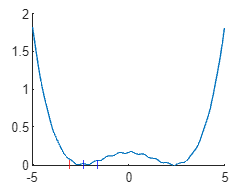


x0 = -0.5;
zad2(f, x0, x0+0.1, 1.5, 0.5, 100)

a_exp = -11.7894

b_exp = 12.5380

i_exp = 15

a_contr = -11.7894

b_contr = 0.3743

i_contr = 2

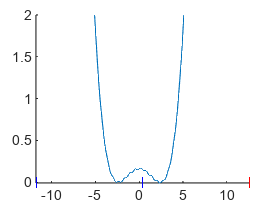

x0 = 32;
zad2(f, x0, x0+0.1, 1.5, 0.5, 100)

a_exp = -3.0629

b_exp = -1.6391

i_exp = 8

a_contr = -1.6391

b_contr = -2.3510

i_contr = 2

x0 = -0.5;
zad2(f, x0, x0+0.1, 1.5, 0.5, 100)

a_exp = -19.2000

b_exp = 19.2000

i_exp = 9

a_contr = 19.2000

b_contr = -4.5475e-13

i_contr = 2

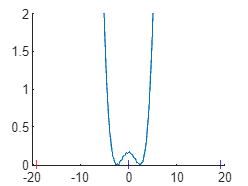

x0 = 32;
zad2(f, x0, x0+0.1, 2, 0.5, 100)

a_exp = -0.2750

b_exp = 0.0062

i_exp = 4

a_contr = 0.0062

b_contr = -0.1344

i_contr = 2

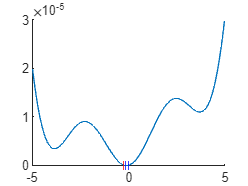


f = fx;
x0 = -0.5;
zad2(f, x0, x0+0.1, 1.5, 0.5, 100)

a_exp = 23.3502

b_exp = 28.1557

i_exp = 11

a_contr = 28.1557

b_contr = 25.7530

i_contr = 2

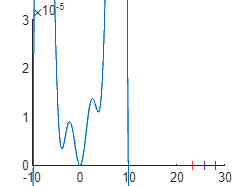

x0 = 32;
zad2(f, x0, x0+0.1, 1.5, 0.5, 100)

a_exp = -0.2750

b_exp = 0.0062

i_exp = 4

a_contr = 0.0062

b_contr = -0.1344

i_contr = 2

x0 = -0.5;
zad2(f, x0, x0+0.1, 1.5, 0.5, 100)

a_exp = 19.2000

b_exp = 28.8000

i_exp = 7

a_contr = 28.8000

b_contr = 26.4000

i_contr = 3

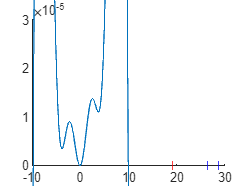

x0 = 32;
zad2(f, x0, x0+0.1, 2, 0.5, 100)

x0=-100 % x0 - punkt startowy

x0 = -100

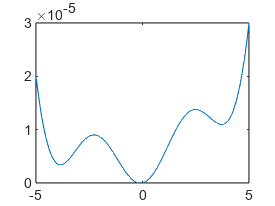

fplot(f)

options = optimset('Display','iter','PlotFcns',@optimplotfval)

options = struct with fields:
                   Display: 'iter'
               MaxFunEvals: []
                   MaxIter: []
                    TolFun: []
                      TolX: []
               FunValCheck: []
                 OutputFcn: []
                  PlotFcns: @optimplotfval
           ActiveConstrTol: []
                 Algorithm: []
    AlwaysHonorConstraints: []
           DerivativeCheck: []
               Diagnostics: []
             DiffMaxChange: []
             DiffMinChange: []
            FinDiffRelStep: []
               FinDiffType: []
         GoalsExactAchieve: []
                GradConstr: []
                   GradObj: []
                   HessFcn: []
                   Hessian: []
                  HessMult: []
               HessPattern: []
                HessUpdate: []
          InitBarrierParam: []
     InitTrustRegionRadius: []
                  Jacobian: []
                 JacobMult: []
              JacobPattern: []
                LargeSca

 
 Iteration   Func-count     min f(x)         Procedure
     0            1          57.4558         
     1            2          57.4558         initial simplex
     2            4         -25.6404         expand
     3            6         -34.0447         reflect
     4            8          -37.273         contract inside
     5           10          -37.273         contract inside
     6           12         -37.5792         contract inside
     7           14         -37.5792         contract inside
     8           16         -37.5844         contract inside
     9           18         -37.5883         contract inside
    10           20         -37.5883         contract inside
    11           22         -37.5886         contract inside
    12           24         -37.5886         contract inside
    13           26         -37.5886         contract inside
    14           28         -37.5886         contract inside
    15           30         -37.5886         contract inside

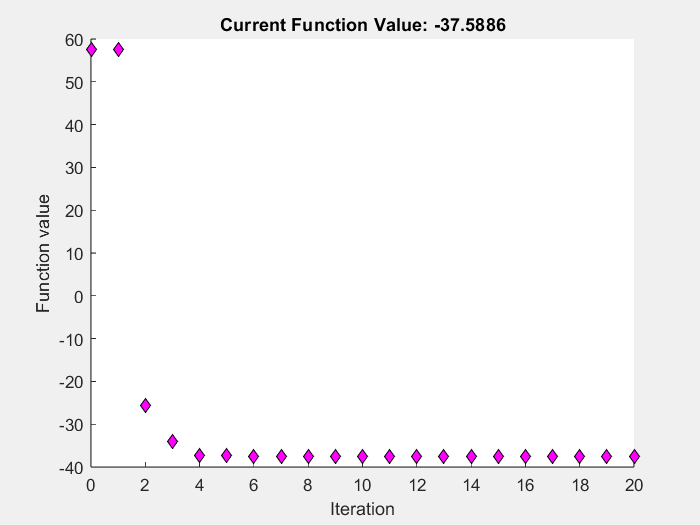

 
Optimization terminated:
 the current x satisfies the termination criteria using OPTIONS.TolX of 1.000000e-04 
 and F(X) satisfies the convergence criteria using OPTIONS.TolFun of 1.000000e-04 



x = -83.9375

x = fminsearch(f,x0,options)

function [] = zad2(f, x0, x1, alpha, beta, Nmax)

[a_exp, b_exp, i_exp] = expansion(f, x0, x1, alpha, Nmax)
[a_contr, b_contr, i_contr] = contraction(f, beta, a_exp, b_exp, Nmax)
figure;
hold on;
fplot(f);
plot([a_exp, b_exp], [0, 0], '|r', [a_contr, b_contr], [0, 0], '|b');
hold off;

end

function [a, b, i] = contraction(f, beta, x0, x1, Nmax)
if f(x0) > f(x1)
    xtemp = x0;
    x0 = x1;
    x1 = xtemp;
end

i = 1;
xj = x1;

while f(x0) < f(xj)
    if i > Nmax
        a = -1.*inf;
        b = inf;
        return;
    end
    xj = x0 + beta.^(i)*(x1 - x0);
    i = i +1;
end
a = x0;
b = xj;
return
end


function [a, b, i] = expansion(f, xzero, x1, alpha, Nmax)

x0 = xzero;
i = 0;
if f(x0) == f(x1)
    a = x0;
    b = x1;
    return
end

if f(x1) > f(x0)
    x1 = -1*(x1 - xzero) + xzero;
    if f(x1) == f(-1*(x1 - xzero) + xzero)
        a = -1*(x1 - xzero) + xzero;
        b = x1;
        return
    end
end

x2 = x1;
x1 = x0;
while f(x1) > f(x2)
    if i > Nmax
        a = -inf;
        b = inf;
        return 
    end
    i = i + 1;
    x0 = x1;
    x1 = x2;
    x2 = alpha * (x2 - xzero) + xzero;
end

if x0 < x2
    a = x0;
    b = x2;
    return
end
a = x2;
b = x0;
return;
end